clear;
load("Data\data_all.mat");
class_labels=[0 1 2 3 4 5 6 7 8 9];

block_size = 2000;
training_size = 1000; % Spesifiser treningsstørrelsen
num_blocks = ceil(size(testv, 1) / block_size);

NN_conf_matrix = zeros(10, 10);

train_data_subset = trainv(1:training_size, :);
train_labels_subset = trainlab(1:training_size);

misclassified_indices = [];
correctly_classified_indices = [];
all_predicted_labels = [];

tic;
for i = 1:num_blocks
    start_idx = (i - 1) * block_size + 1;
    end_idx = min(i * block_size, size(testv, 1));
    test_block = testv(start_idx:end_idx, :);

    predicted_labels_block = classify_nn(train_data_subset, train_labels_subset, test_block);
    all_predicted_labels = [all_predicted_labels; predicted_labels_block];
    
    NN_conf_matrix = NN_conf_matrix + confusionmat(testlab(start_idx:end_idx), predicted_labels_block);
    
    misclassified_indices_block = find(predicted_labels_block ~= testlab(start_idx:end_idx));
    correctly_classified_indices_block = find(predicted_labels_block == testlab(start_idx:end_idx));
    
    misclassified_indices_block = start_idx - 1 + misclassified_indices_block;
    correctly_classified_indices_block = start_idx - 1 + correctly_classified_indices_block;

    misclassified_indices = [misclassified_indices; misclassified_indices_block(:)]; 
    correctly_classified_indices = [correctly_classified_indices; correctly_classified_indices_block(:)];
end
t_NN = toc;
error_rate = 1 - sum(diag(NN_conf_matrix)) / sum(NN_conf_matrix(:));

time_str = datestr(seconds(t_NN), 'HH:MM:SS');
fprintf('Training time: %s\n', time_str);

Training time: 00:00:18


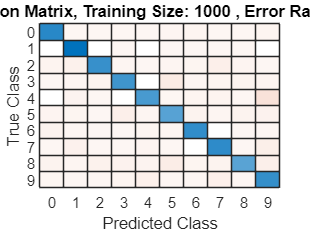


figure;
confusionchart(NN_conf_matrix, class_labels);
title(['Confusion Matrix, Training Size: ',num2str(training_size),' , Error Rate: ', num2str(round(error_rate * 100,2)), '%']);

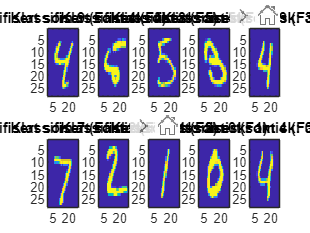


figure;
num_misclassified = min(5, length(misclassified_indices)); % Plot up to 5 misclassified pictures
for i = 1:num_misclassified
    subplot(2, num_misclassified, i);
    x = zeros(28, 28);
    x(:) = testv(misclassified_indices(i), :);
    image(x');
    title(['Klassifisert som ' num2str(all_predicted_labels(misclassified_indices(i))) ' (Faktisk: ' num2str(testlab(misclassified_indices(i))) ')']);
end

num_correctly_classified = min(5, length(correctly_classified_indices)); % Plot up to 5 correctly classified pictures
for i = 1:num_correctly_classified
    subplot(2, num_correctly_classified, num_misclassified + i);
    x = zeros(28, 28);
    x(:) = testv(correctly_classified_indices(i), :);
    image(x');
    title(['Klassifisert som ' num2str(all_predicted_labels(correctly_classified_indices(i))) ' (Faktisk: ' num2str(testlab(correctly_classified_indices(i))) ')']);
end